%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312



t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


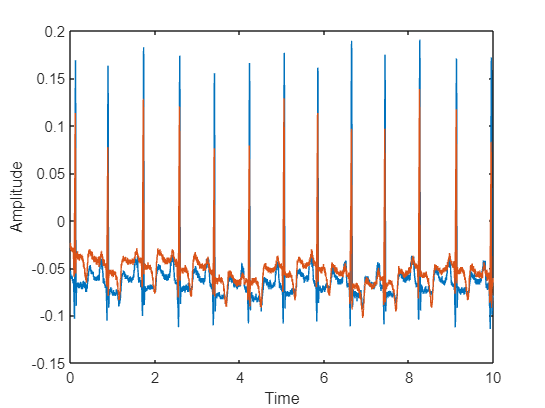

plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")






% Determine minimum and maximum values in each channel
ecg_min = min(a_cut);
ecg_max = max(a_cut);

% Shift the range so that it starts at 0
ecg_shifted = a_cut - ecg_min;

% Divide each value by the range of values to scale the waveform
ecg_normalized = zeros(size(ecg_shifted));
ecg_normalized(:,1) = ecg_shifted(:,1) / (ecg_max(1) - ecg_min(1));
ecg_normalized(:,2) = ecg_shifted(:,2) / (ecg_max(2) - ecg_min(2));

% Check the size and values of the normalized ECG waveform
disp(size(ecg_normalized));

        3600           2



disp(ecg_normalized(1:10,:));

    0.2019    0.3279
    0.1987    0.3036
    0.1923    0.3036
    0.1827    0.2996
    0.1827    0.2955
    0.1731    0.3077
    0.1795    0.3117
    0.1827    0.3077
    0.1859    0.3077
    0.1827    0.2955



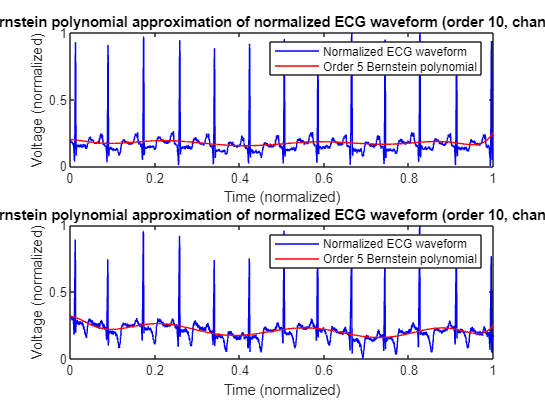




% Generate Bernstein polynomial approximations of order 5 for both channels
n = 10;
t = linspace(0, 1, size(ecg_normalized, 1));
p = bernstein(n, t);
x1 = ecg_normalized(:, 1); % Select the first channel of the normalized ECG waveform
a1 = p \ x1;
y1 = p * a1;

x2 = ecg_normalized(:, 2); % Select the second channel of the normalized ECG waveform
a2 = p \ x2;
y2 = p * a2;

% Plot the normalized ECG waveform and the Bernstein polynomial approximations for both channels
figure;
subplot(2, 1, 1);
plot(t, ecg_normalized(:, 1), 'b');
hold on;
plot(t, y1, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 10, channel 1)');
legend('Normalized ECG waveform', 'Order 5 Bernstein polynomial');

subplot(2, 1, 2);
plot(t, ecg_normalized(:, 2), 'b');
hold on;
plot(t, y2, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 10, channel 2)');
legend('Normalized ECG waveform', 'Order 5 Bernstein polynomial');